# Exercises 4 (Lecture 7)

**Exercise 1. **Generate some data using`y = rand(1,80)>.3;`. These data consist of 0s and 1s, representing class assignments. Now suppose we have a model that gives the following predictions for the data: `ypredict =` `rand(size(y))>.5;`. (Yes, the model is just a random coin-flipper.) What is the percent correct achieved by themodel? Of the data points assigned to class 0, what is the percent correct achieved by the model?


% data
y = rand(1,80) > 0.3;

% model fit
ypredict = rand(size(y)) > 0.5;

% Total model correctness
pctmodel = sum(ypredict==y) / length(y) * 100

pctmodel = 48.7500


% Model correctness for 0 value
pctzeromodel = sum(ypredict==0) / length(y==0) * 100

pctzeromodel = 51.2500

**Exercise 2. **Suppose we measure the height and weight of two groups, males and females. Generate some hypothetical data as follows:

`heightM = 50 + 10*randn(1,100); heightF = 45 + 9*randn(1,60);`

`weightM = 50 + 2*heightM + 10*randn(size(heightM)); weightF = 40 + 3*heightF + 10*randn(size(heightF));`

Visualize these data using a scatter plot. Then perform nearest-prototype classification to see how well we can predict gender based on measurement of height and weight. What percentage of data points in our sample are correctly classified? Draw the decision boundary of the classifier on the plot.


heightM = 50 + 10*randn(1,100);
heightF = 55 + 9*rand(1,60);

weightM = 50 + 2*heightM + 10*randn(size(heightM));
weightF = 40 + 3*heightF + 10*randn(size(heightF));


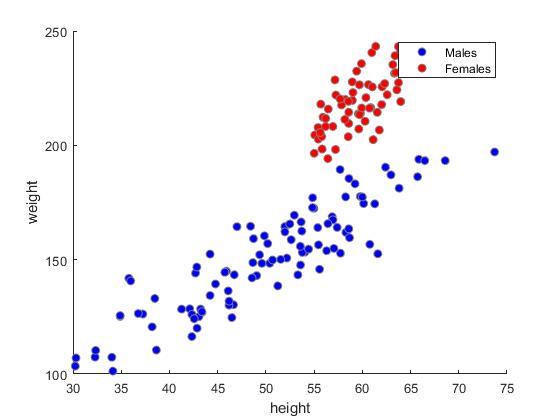

figure; hold on;
males = scatter(heightM , weightM,'b', 'filled');
females = scatter(heightF , weightF,'r', 'filled');

set([males females], 'MarkerEdgeColor', [.5 .5 .5]);
legend([males, females], {'Males' 'Females'})
xlabel('height')
ylabel('weight')

% prepare data
classMales = [heightM; weightM];
classFemales = [heightF; weightF];

ax = axis;

xvals = linspace(ax(1), ax(2),200);
yvals = linspace(ax(3), ax(4),200);

[xx, yy] = meshgrid(xvals,yvals);
gridX = [xx(:) yy(:)];

% Perform nearest-prototype classifier

% Find centres of the classes
centroidMales = mean(classMales, 2);
centroidFemales = mean(classFemales, 2);

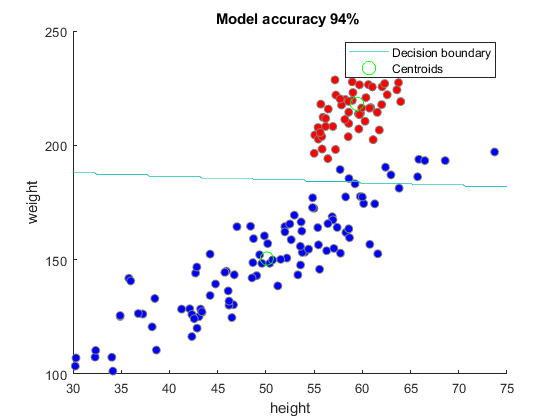


% calculate the distance to class Males
%distanceToMales = sqrt(sum((gridX - centroidMales).^2,2));
distanceToMales = sqrt(sum(bsxfun(@minus,gridX,centroidMales').^2,2));
% calculate the distance to class Females
%distanceToFemales = sqrt(sum((gridX - centroidFemales).^2,2));
distanceToFemales = sqrt(sum(bsxfun(@minus,gridX,centroidFemales').^2,2));

% Create a decision boundary
% 1 for Males, 0 for Females
outputimage = distanceToMales > distanceToFemales;
outputimage = reshape(outputimage, [length(xvals) length(yvals)]);

color = distanceToMales > distanceToFemales;                                                                                                                                                                                                                                                                    color)
% Calculate the model accuracy

X = [heightM' weightM'; ...
    heightF' weightF';];

y = [ones(length(heightM),1);
    zeros(length(heightF),1);];

distanceToMales = sqrt(sum(bsxfun(@minus,X,centroidMales').^2,2));
distanceToFemales = sqrt(sum(bsxfun(@minus,X,centroidFemales').^2,2));

% Suppose that calculated distance to males is lower than to females
pred = distanceToMales < distanceToFemales;

% Test how exactly the prediction is equal to the sample
pred = pred == y;

% Calculate accuracy
acc = sum(pred) / length(pred) * 100;

% Draw a centroid for men
centroids = [centroidMales, centroidFemales];
x = centroids(1,:);
y = centroids(2,:);

[d, h2] = contour(xvals, yvals, outputimage, [.7 .7]);
p1 = plot(x , y,'go', 'MarkerSize', 10);

legend([h2,p1],"Decision boundary", "Centroids");
title(sprintf("Model accuracy %.f%% %", acc))